% Nome: Caio Gomes Gonçalves    
% Matrícula: 16.2.1767
% Questão 1) Ponto 1

clc;
clear all;


Robô Planar RR

Limites Mecânicos do Servo do Levantamento do Braço:

    Mínimo: 0°.

    Máximo: +180°.

Limites Mecânicos da Servo do Cotovelo do Braço:

     Mínimo: -50°.

     Máximo: +90°.

%Definição dos parâmetros do Robô RR

a1=20;
a2=10;

alfa=-pi/2;% parâmetro necessário para que a posição zero do robô tenha a configuração desejada na qual o eixo x2 (cotovelo)  está a -90º em relação a x1 (levantamento do braço)

%Espaço de Trabalho

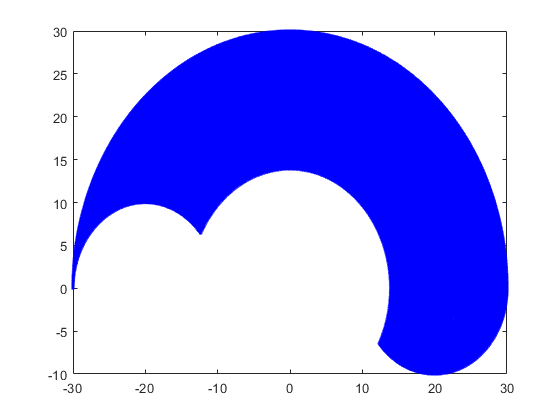

i=0;

theta1_limInf=0;%limite inferior de theta 1 em graus
theta1_limSup=180;%limite superior de theta 1 em graus
theta2_limInf=-50;%limite inferior de theta 2 em graus
theta2_limSup=90;%limite superior de theta 2 em graus

theta1_limInf=deg2rad(theta1_limInf);
theta1_limSup=deg2rad(theta1_limSup);
theta2_limInf=deg2rad(theta2_limInf);
theta2_limSup=deg2rad(theta2_limSup);


for theta1=theta1_limInf:(theta1_limSup-theta1_limInf)/199:theta1_limSup,
    for theta2=theta2_limInf:(theta2_limSup-theta2_limInf)/199:theta2_limSup,
        i=i+1;
        x(i)=a1*cos(theta1)+a2*cos(theta1+theta2+alfa);%cinemática direta de posição x
        y(i)=a1*sin(theta1)+a2*sin(theta1+theta2+alfa); %cinemática direta de posição y
    end
end
plot(x,y,'.b');
hold on;

%Definição da Trajetória Retilínea
p0_r=[-7.465, 24.34];%xi,yi
p1_r=[12.02, 11.7];%xf,yf

Dx=p1_r(1)-p0_r(1); 
Dy=p1_r(2)-p0_r(2);
A=Dy/Dx;
b=p0_r(1,2)-A*p0_r(1,1);
k=0;
n_pontos_r=80;
for i=p0_r(1,1):(p1_r(1,1)-p0_r(1,1))/(n_pontos_r-1):p1_r(1,1),
    k=k+1;
    tx_r(k)=i;
    ty_r(k)=A*tx_r(k)+b ;
end

%Definição do Tempo da Trajetória Retilínea e do Intervalo de Amostragem

Tempo_r=30e-3; % Intervalo de amostragem igual a 40 milissegundos

T_r(1)=0;
for i=2:n_pontos_r,
    T_r(i)=T_r(i-1)+Tempo_r;
end

%Definição dos Intervalos de Tempo da Trajetória Retilínea

dT_r=diff(T_r);

%Controlador Proporcional para Trajetória Retilínea

K_r=[10,0;0,10];

# Definição dos parâmetros do Robô RR

## Posição Inicial

format compact;
L1 = 20; %link 1 length
L2 = 10; %link 2 length
a1 = L1;
a2 = L2;

xPos = -7.465; %x position of end-effector
yPos = 24.34;%y position of end-effector

P = [xPos yPos]; %end-effector position vector

theta2 = -acos((xPos^2 + yPos^2 - L1^2 - L2^2)/(2*L1*L2));
theta1 = atan2(yPos,xPos) - atan2((L2*sin(theta2)),(L1 + L2*cos(theta2)));
% theta3 = 

theta2_d = rad2deg(theta2)

theta2_d = -53.4669

theta1_d = rad2deg(theta1)

theta1_d = 123.9202


alfa = -pi/2;

q_r(:,1) = [theta1;(theta2-alfa)]; %joint angle vector

Rotz1 = [cos(theta1) -sin(theta1) 0 0;...
          sin(theta1)  cos(theta1) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans1 = [1 0 0 L1;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
Rotz2 = [cos(theta2) -sin(theta2) 0 0;...
          sin(theta2)  cos(theta2) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans2 = [1 0 0 L2;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];

T = Rotz1*Trans1*Rotz2*Trans2

T =     0.3346   -0.9424         0   -7.8150
    0.9424    0.3346         0   26.0200
         0         0    1.0000         0
         0         0         0    1.0000


T_01 = Rotz1*Trans1

T_01 =    -0.5580   -0.8298         0  -11.1608
    0.8298   -0.5580         0   16.5963
         0         0    1.0000         0
         0         0         0    1.0000



T_02 = T_01*Rotz2*Trans2

T_02 =     0.3346   -0.9424         0   -7.8150
    0.9424    0.3346         0   26.0200
         0         0    1.0000         0
         0         0         0    1.0000


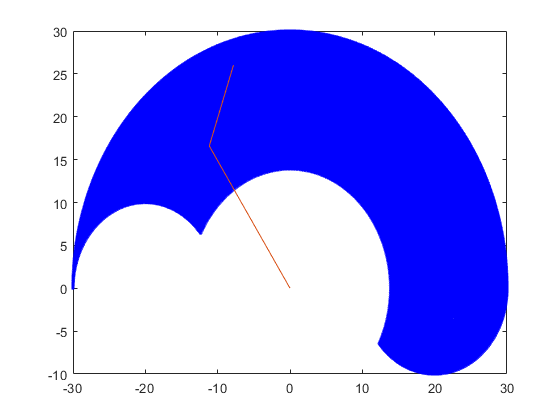


P = [0;0;0;1];
P1 = T_01*P; P2 = T_02*P;
hold on;plot([0 P1(1) P2(1)],[0 P1(2) P2(2)]);

%Definição das velocidade desejadas do efetuador para trajetória Retilínea

dtx_r=diff(tx_r);
dty_r=diff(ty_r);

%CONTROLE DE TRAJETÓRIA RETILÍNEA

for i=1:n_pontos_r,
    X_pot_r(:,i)=[a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa);
                a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)]; %posição corrente q_p do efetuador
            
    Xd_r(:,i)=[tx_r(i);
        ty_r(i)]; %posicao desejada (pd ou xd)
    
    e_r(:,i)=Xd_r(:,i)-X_pot_r(:,i); %erro de posição(e_p)
    
    if(i<n_pontos_r)
        
        %velocidade pd_ponto (feedfoward)
        dXd_r(:,i)=[dtx_r(i)./dT_r(:,i); dty_r(i)./dT_r(:,i)];
        
        %lei de controle u_p_barra - velocidade linear do efetuador relativo a contribuição da velocidade das juntas
        u_r(:,i)=K_r*e_r(:,i)+dXd_r(:,i);
        
        %velocidade das juntas qp_ponto=up -> inverso do jacobiano*lei de controle (u = (j(q_p)^-1*up)
        dq_r(:,i)=1/(a1*a2*sin(q_r(2,i)+alfa))*([a2*cos(q_r(1,i)+q_r(2,i)+alfa), a2*sin(q_r(1,i)+q_r(2,i)+alfa); -a1*cos(q_r(1,i))-a2*cos(q_r(1,i)+q_r(2,i)+alfa), -a1*sin(q_r(1,i))-a2*sin(q_r(1,i)+q_r(2,i)+alfa)])*u_r(:,i);
 
        
        %limitando a vel das juntas 60°/s%
        vel_lim_pos(:,i)=deg2rad(60);%em rad
        vel_lim_neg(:,i)=deg2rad(-60);%em rad
               
        if (dq_r(1,i) < 0)
            if (abs(dq_r(1,i)) > vel_lim_pos(:,i))
                dq_r(1,i) = vel_lim_neg(:,i);
            end
        end 
        if (dq_r(1,i) > 0)
            if (abs(dq_r(1,i)) > vel_lim_pos(:,i))
                dq_r(1,i) = vel_lim_pos(:,i);
            end
        end
        
         if (dq_r(2,i) < 0)
            if (abs(dq_r(2,i)) > vel_lim_pos(:,i))
                dq_r(2,i) = vel_lim_neg(:,i);
            end
         end 
         if (dq_r(2,i) > 0)
            if (abs(dq_r(2,i)) > vel_lim_pos(:,i))
                dq_r(2,i) = vel_lim_pos(:,i);
            end
         end
         
        %posição corrente q_p
        q_r(:,i+1)=q_r(:,i)+dq_r(:,i)*dT_r(:,i);
        
        %limites mecanicos
        if q_r(1,i+1)>theta1_limSup,%Limite Mecânico Medido
           q_r(1,i+1)=theta1_limSup;
        end
        if q_r(1,i+1)<theta1_limInf, %Limite Mecânico Medido
           q_r(1,i+1)=theta1_limInf;
        end
        if q_r(2,i+1)>theta2_limSup, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limSup;
        end
        if q_r(2,i+1)<theta2_limInf, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limInf;
        end
    end
end

%Gráfico da Trajetória Retilínea juntamente com Espaço de Trabalho

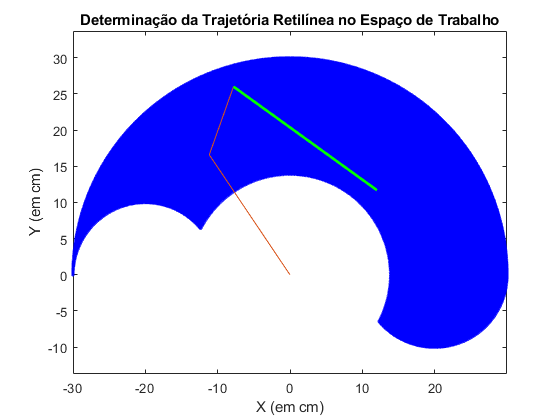

plot(tx_r,ty_r,'g', "LineWidth",2);
xlabel('X (em cm)'), ylabel('Y (em cm)'), title('Determinação da Trajetória Retilínea no Espaço de Trabalho');
axis equal;

%Conversão de Radianos para Graus

q_r=rad2deg(q_r); %Variáveis de Juntas para Trajetória Retilínea
dq_r=rad2deg(dq_r); %Velocidades das Juntas para Trajetória Retilínea

%Gráficos Pedidos

%********Trajetória Desejada X Trajetória Efetuada*************************

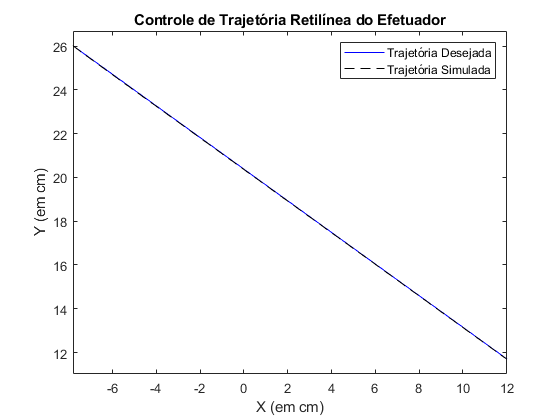

%Trajetória Retilínea
figure,
plot(tx_r,ty_r,'b',X_pot_r(1,:),X_pot_r(2,:),'k--');
ylabel('Y (em cm)'), xlabel('X (em cm)'), title('Controle de Trajetória Retilínea do Efetuador');
legend('Trajetória Desejada','Trajetória Simulada');
axis equal

%********Posições Angulares das Juntas X Tempo*****************************

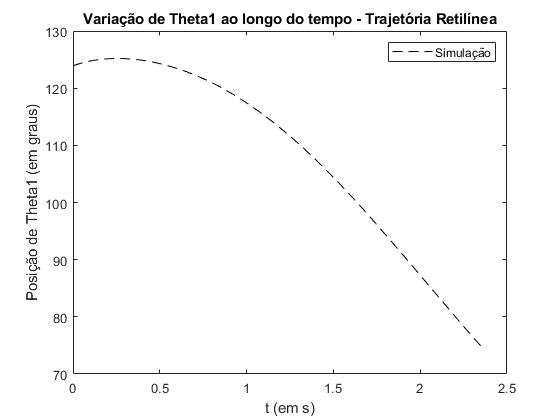

%Trajetória Retilínea
figure,
plot(T_r,q_r(1,:),'k--');
ylabel('Posição de Theta1 (em graus)'), xlabel('t (em s)'), title('Variação de Theta1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

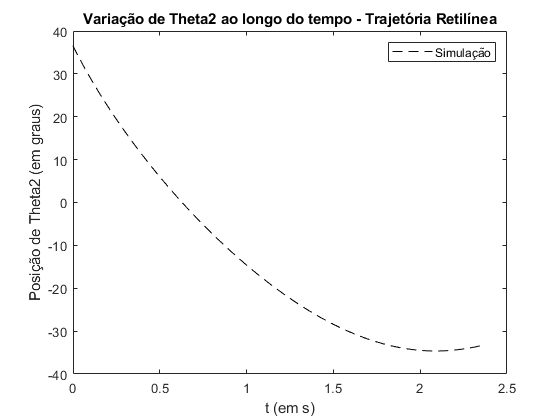

%axis equal;
figure,
plot(T_r,q_r(2,:),'k--');
ylabel('Posição de Theta2 (em graus)'), xlabel('t (em s)'), title('Variação de Theta2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

%axis equal;

%********Erro de Posição X Tempo*******************************************

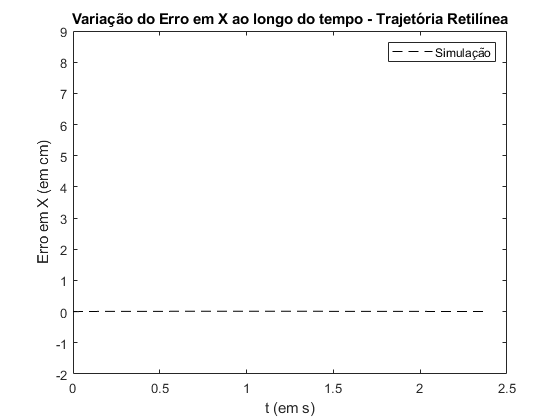

%Trajetória Retilínea
figure,
plot(T_r,e_r(1,:),'k--');
ylabel('Erro em X (em cm)'), xlabel('t (em s)'), title('Variação do Erro em X ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-2,9]);

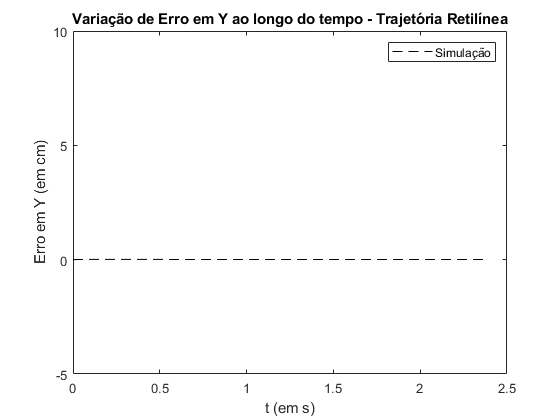

%axis equal;
figure,
plot(T_r,e_r(2,:),'k--');
ylabel('Erro em Y (em cm)'), xlabel('t (em s)'), title('Variação de Erro em Y ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-5,10]);

%axis equal;

%********Velocidade das Juntas X Tempo*******************************************

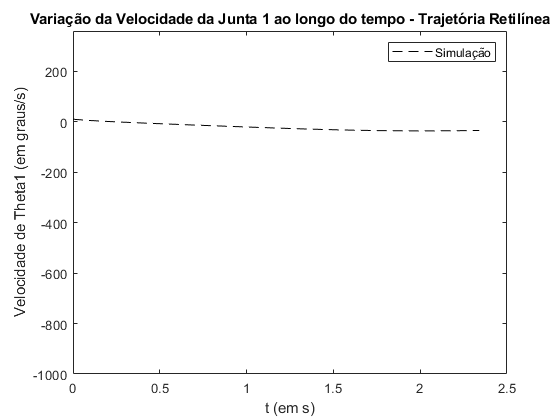

%Trajetória Retilínea
figure,
plot(T_r(1:n_pontos_r-1),dq_r(1,:),'k--');
ylabel('Velocidade de Theta1 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-1000,360]);

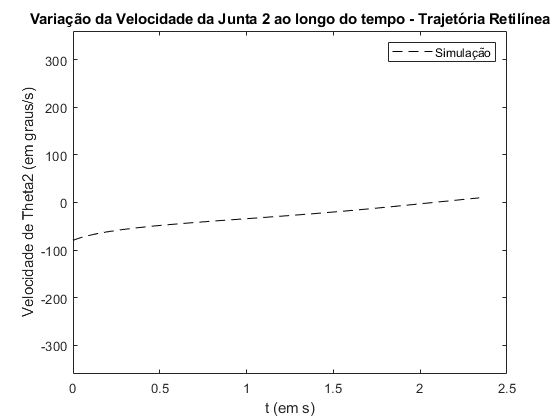

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(2,:),'k--');
ylabel('Velocidade de Theta2 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-360,360]);